load and pick data

close all;
clear;
clc;
load gaitdata.mat;
load actuatordata.mat;

%keep only sagittal hip data
TBL = removevars(gaitdata,{'aKsag', 'aAsag', 'mKsag_abs', 'mKsag_max', 'mKsag_min', 'mKsag_rel', 'mKsag_rms', 'pKsag_abs', 'pKsag_max', 'pKsag_min', 'pKsag_rel', 'mAsag_abs', 'mAsag_max', 'mAsag_min', 'mAsag_rel', 'mAsag_rms', 'pAsag_abs', 'pAsag_max', 'pAsag_min', 'pAsag_rel'});

% get length and patient identifiers
pat = TBL{:,1};
nr= length(pat)

nr = 31


% initialize arrays
KS_minPabsPeak_all=NaN(1,nr);
KS_minMrms_all=NaN(1,nr);
KS_breakevenPabsPeak_all=NaN(1,nr);
KS_breakevenMrms_all=NaN(1,nr);
Nfeasrange_all = NaN(2,nr);
mnospring_all = NaN(101,nr);
pnospring_all = NaN(101,nr);
idpmin_all = NaN(1,nr);
idmmin_all = NaN(1,nr);

% zero crossing function
zci = @(v) find(v(:).*circshift(v(:), [-1 0]) <= 0);

Numerical differentiation and low-pass filtering, assumption made on cadence

for j=1:nr
%for j=1:2
% Tgait = stride period
Tgait = 1.2%seconds
%lowpass filter frequency
flp = 6;
flp_load = 3;

% select patient
id = j;

H = diff_joints_v2_hiponly(TBL(id,:),Tgait,flp,flp_load); 

Evaluate motor feasability:

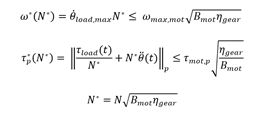

Tload should be the sum of the exo-only actuation load and the desired assistance load moment

determining exo-only load has been omitted for this example. It should be derived via inverse dynamics of an exo model

% choose actuator and voltage
act_id = 6;
Voltage_used = 24;                      % is used to adapt speed proportionally
overload = 1.2    % overloading with additional cooling ?
act_name = actuatordata.NAME{act_id};
Bmot = actuatordata.INERTIAkgm(act_id) ; % gearbox inertia is ignored
Tnom = actuatordata.NOMINALTORQUENm(act_id) * overload;
Tmax = actuatordata.PEAKTORQUENm(act_id);
Tstall= actuatordata.STALLTORQUENm(act_id);
wnom = 	actuatordata.NOMINALSPEEDrpm(act_id) * 2 * pi /60 * Voltage_used/actuatordata.NOMINALVOLTAGEV(act_id);
wnoload = actuatordata.NOLOADSPEEDrpm(act_id) * 2 * pi /60;

%gearing efficiency
eta =1;

%normalisation factors
f1 = sqrt(Bmot/eta);
f2 = sqrt(Bmot*eta);
wmot = wnom * f2;
Tmotmax = Tmax/f1;
Tmotrms = Tnom/f1;


%id = 11;
assistfactor = 1;
plotpat_hiponly(pat,H,id)

% example: 
joint = H;
joint_all(j) = joint;
Npoints = 500;
Nrange = [0.01 3];

Motor is feasable if X markers are above their respective lines


[N,omeganorm,momentnormRms, momentnormMax]=normratio_rms_max(joint,Nrange,Npoints,true,assistfactor);

figure
% rms curve
plot(omeganorm,momentnormRms,'b',omeganorm,cummin(momentnormRms),'b:',wmot,Tmotrms,'xb')
hold on
% get intersects
idxminrms = zci(momentnormRms-Tmotrms);
idxmax = zci(omeganorm-wmot);
its1 = [omeganorm(idxminrms(1)) Tmotrms];
its2 = [wmot, momentnormRms(idxmax(1))];
% max curve
plot(omeganorm,momentnormMax,'r',omeganorm,cummin(momentnormMax),'r:',wmot,Tmotmax,'xr')
% get intersects
idxminpk = zci(momentnormMax-Tmotmax);
its3 = [omeganorm(idxminpk(1)) Tmotmax];
its4 = [wmot, momentnormMax(idxmax(1))];
% plot intersects
plot([its1(1) its2(1)], [its1(2) its2(2)], '.b');
line([its1(1) wmot its2(1)],[its1(2), Tmotrms, its2(2)],'LineStyle','--');
plot([its3(1) its4(1)], [its3(2) its4(2)], '.r');
line([its3(1) wmot its4(1)],[its3(2), Tmotmax its4(2)],'LineStyle','--', 'Color', 'r');

hold off
legend('rms norm','MLB rms', ['rms ' act_name],'max norm','MLB max', ['max ' act_name]);
xlim([0 10]);
xlabel('$\omega^*\,[\sqrt{kg\,m^2}\,rad/s]$', "Interpreter","latex", "FontSize",14);
ylim([0 250]);
ylabel('$\tau^*\,[\frac{Nm}{\sqrt{kg\,m^2}}]$', "Interpreter","latex", "FontSize",14);
title([joint.name pat(id)]);

cond1 = Tmotrms > momentnormRms;
cond2 = Tmotmax > momentnormMax;
cond3 = wmot > omeganorm;
[~,idmin] = min(momentnormRms);
cond4 = [true(idmin,1);false(Npoints-idmin,1)];
Nfeas = N(cond1&cond2&cond3); %all conditions
%Nfeas = N(cond1&cond3); %ignore peak condition
Nfeasrange = [min(Nfeas),min(Nfeas)/f2; max(Nfeas),max(Nfeas)/f2]
Noptimal = [min(max(Nfeas),N(idmin))/f2 min(max(Nfeas),N(idmin))/f2];

try
    Nfeasrange_all(:,j)=Nfeasrange(:,2);
catch ME
end

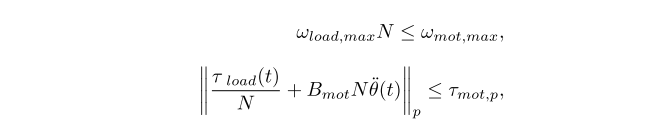

Pick gear ratio and evaluate margins

Nsel = 81

% speed margin
omega_load_max_atmot = max(abs(joint.ad))*Nsel;
moment_load_rms_atmot =  rms(-1*assistfactor*joint.m_abs./(Nsel*eta) + Bmot * Nsel * joint.add);
moment_load_max_atmot = max(abs(-1*assistfactor*joint.m_abs./(Nsel*eta) + Bmot * Nsel * joint.add));

speed_margin = (wnom - omega_load_max_atmot)/wnom
moment_margin_rms = (Tnom - moment_load_rms_atmot)/Tnom
moment_margin_max = (Tmax - moment_load_max_atmot)/Tmax

SEA spring stiffness

The spring affects the motor torque and velocity profile, and thus the power profile.

Efficiencies are omitted

minimize motor power or torque

Tgait = 1.2000

overload = 1.2000

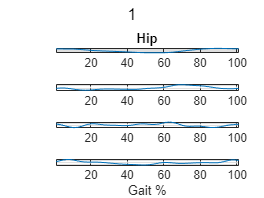

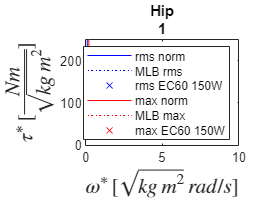

Nfeasrange =     0.1418   15.7582
    1.0526  116.9561


Nsel = 81

speed_margin = 0.3077

moment_margin_rms = 0.7199

moment_margin_max = 0.7425

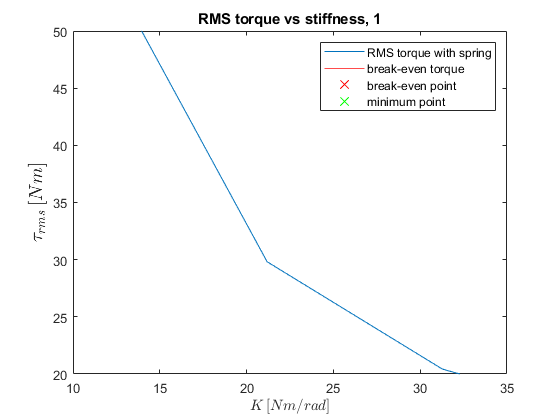

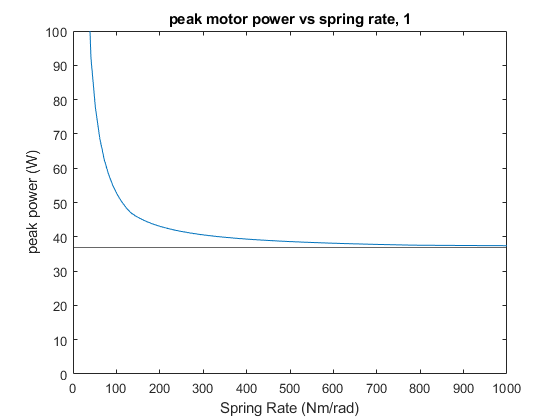

Tgait = 1.2000

overload = 1.2000

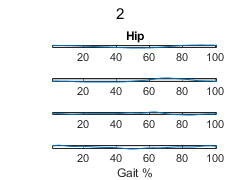

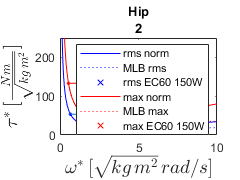

Nfeasrange =     0.1898   21.0844
    0.9028  100.3117


Nsel = 81

speed_margin = 0.1960

moment_margin_rms = 0.6374

moment_margin_max = 0.7149

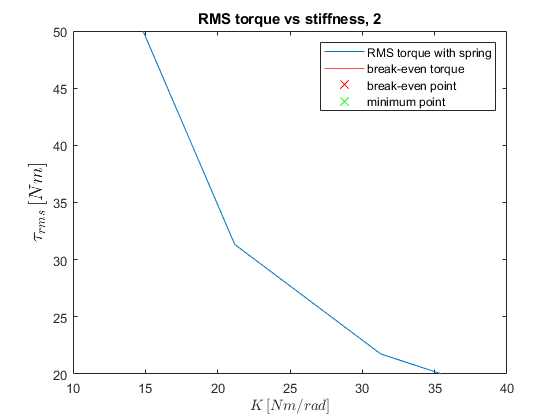

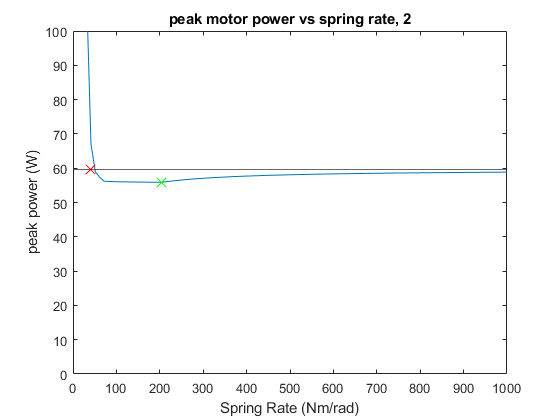

Tgait = 1.2000

overload = 1.2000

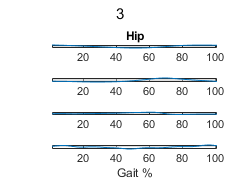

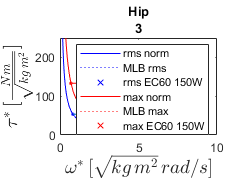

Nfeasrange =     0.3036   33.7341
    1.1844  131.6032


Nsel = 81

speed_margin = 0.3852

moment_margin_rms = 0.5124

moment_margin_max = 0.5957

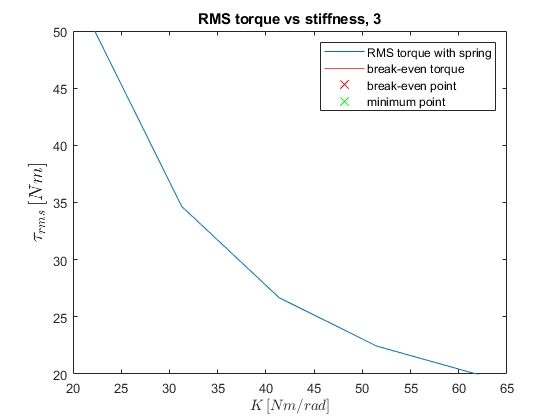

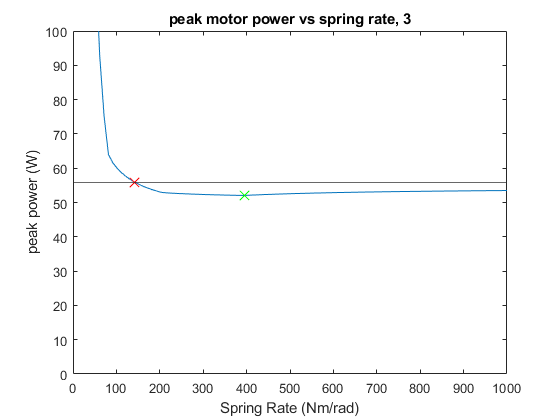

Tgait = 1.2000

overload = 1.2000

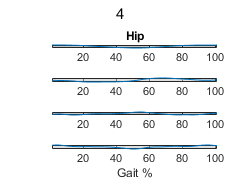

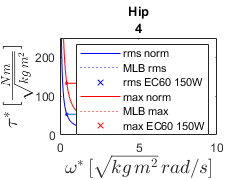

Nfeasrange =     0.1838   20.4186
    1.3462  149.5792


Nsel = 81

speed_margin = 0.4600

moment_margin_rms = 0.6685

moment_margin_max = 0.6565

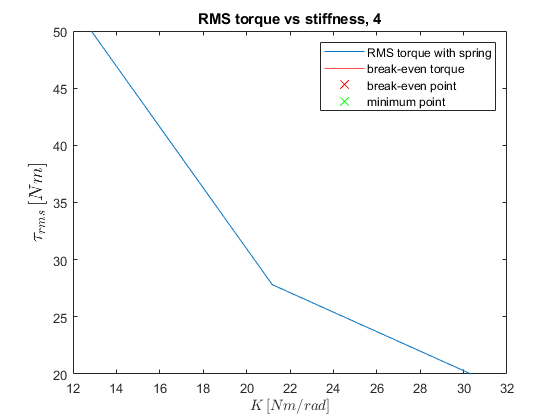

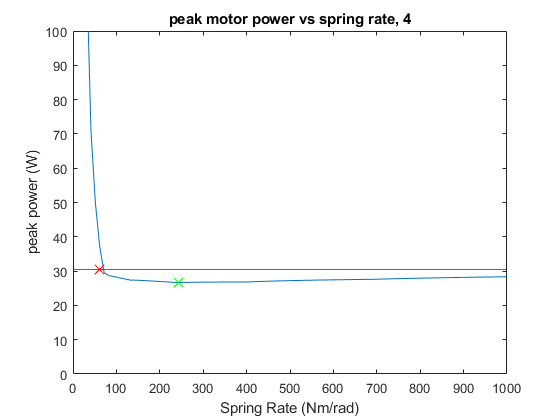

Tgait = 1.2000

overload = 1.2000

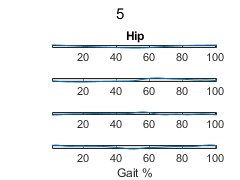

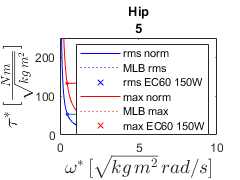

Nfeasrange =     0.2017   22.4159
    1.3702  152.2423


Nsel = 81

speed_margin = 0.4690

moment_margin_rms = 0.6489

moment_margin_max = 0.6605

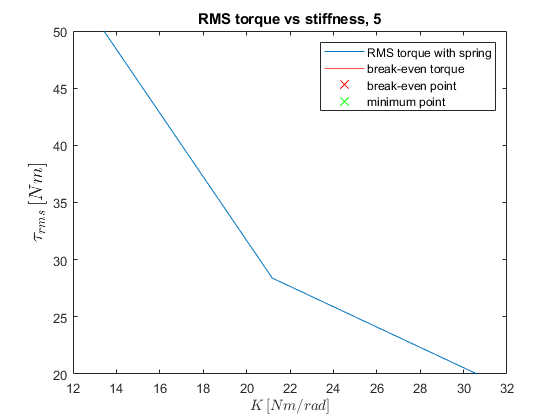

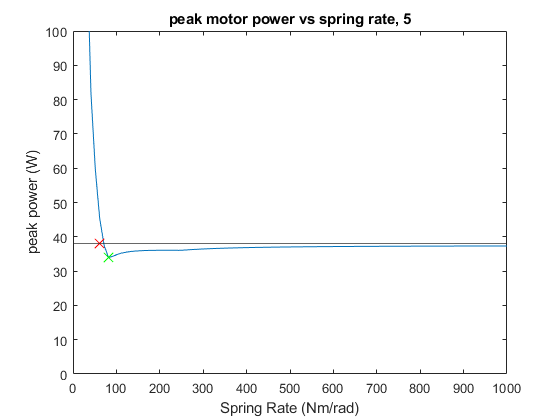

Tgait = 1.2000

overload = 1.2000

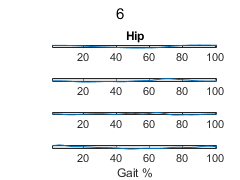

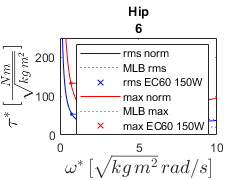

Nfeasrange =     0.1958   21.7502
    0.8369   92.9882


Nsel = 81

speed_margin = 0.1312

moment_margin_rms = 0.6096

moment_margin_max = 0.6885

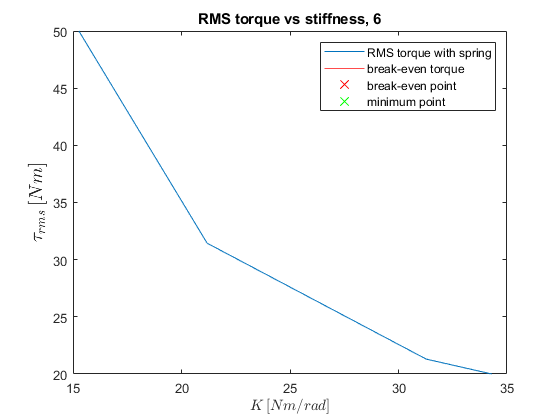

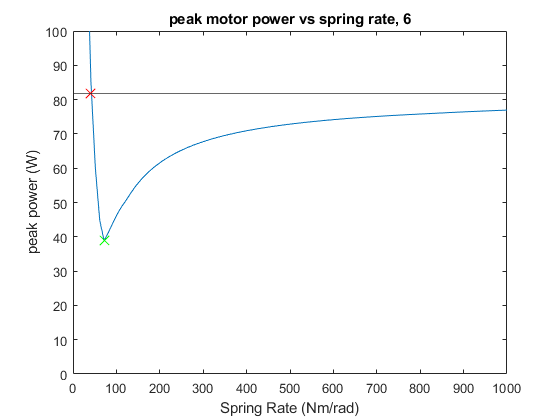

Tgait = 1.2000

overload = 1.2000

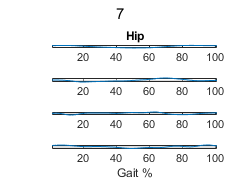

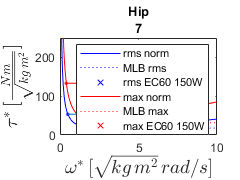

Nfeasrange =     0.1538   17.0897
    0.9747  108.3010


Nsel = 81

speed_margin = 0.2529

moment_margin_rms = 0.6690

moment_margin_max = 0.7599

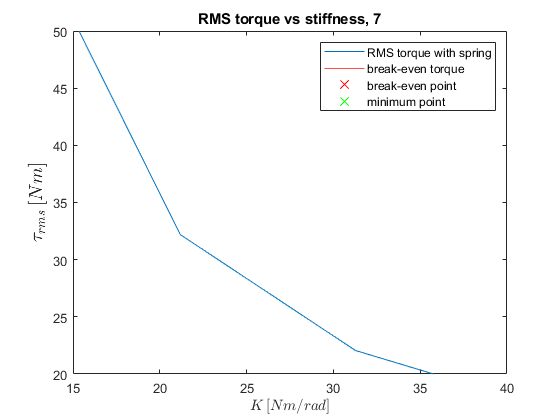

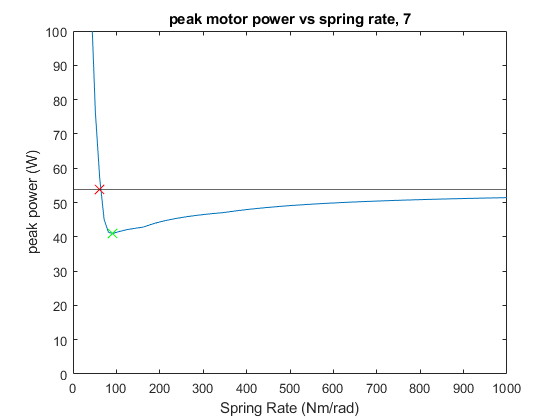

Tgait = 1.2000

overload = 1.2000

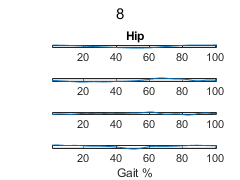

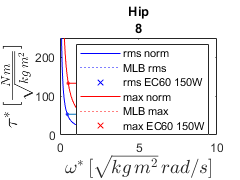

Nfeasrange =     0.1778   19.7528
    1.0826  120.2850


Nsel = 81

speed_margin = 0.3267

moment_margin_rms = 0.6851

moment_margin_max = 0.7094

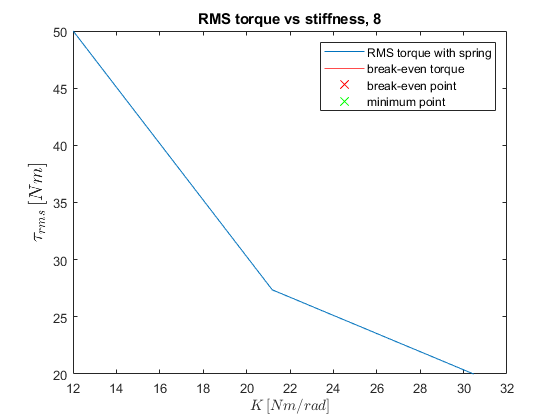

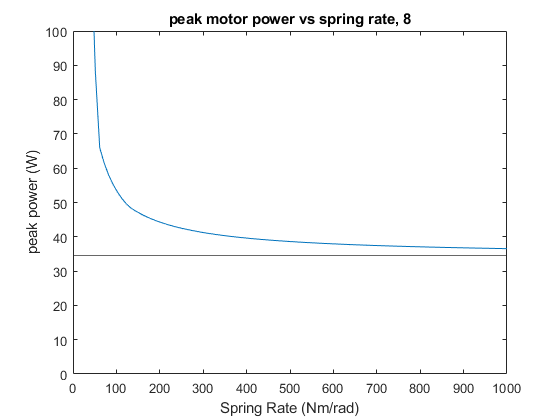

Tgait = 1.2000

overload = 1.2000

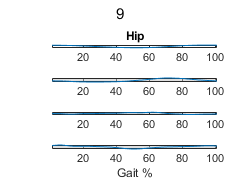

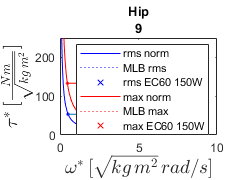

Nfeasrange =     0.2017   22.4159
    1.2443  138.2610


Nsel = 81

speed_margin = 0.4158

moment_margin_rms = 0.6403

moment_margin_max = 0.6929

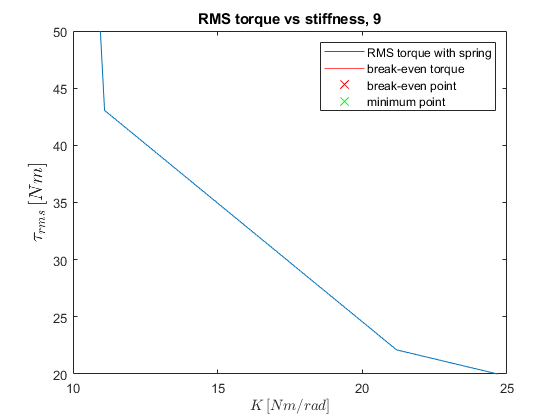

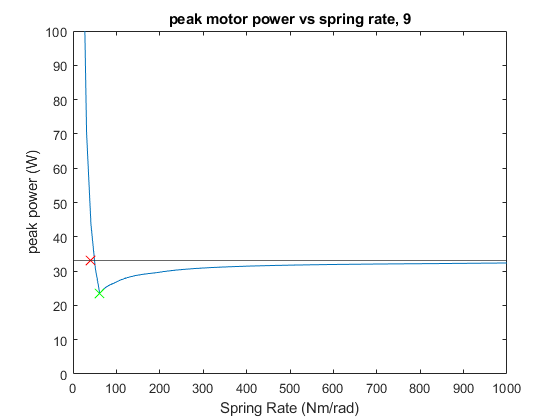

Tgait = 1.2000

overload = 1.2000

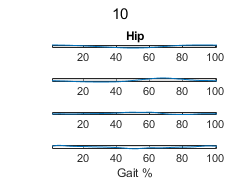

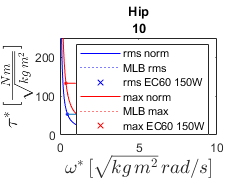

Nfeasrange =     0.1718   19.0871
    1.1485  127.6086


Nsel = 81

speed_margin = 0.3674

moment_margin_rms = 0.6747

moment_margin_max = 0.7307

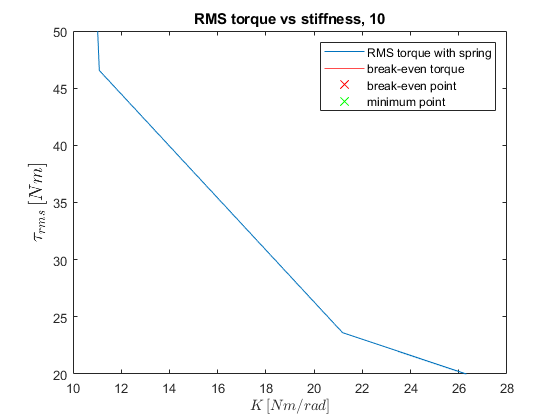

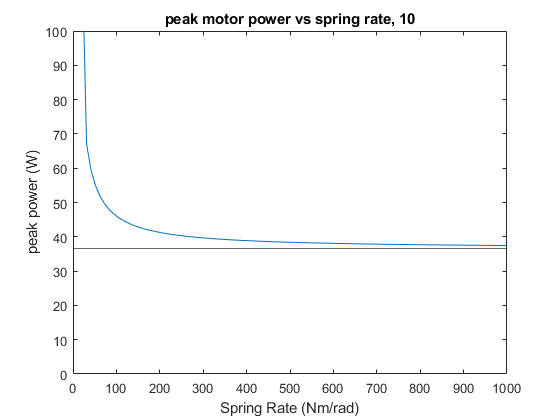

Tgait = 1.2000

overload = 1.2000

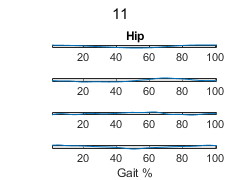

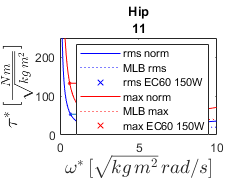

Nfeasrange =     0.2077   23.0817
    0.9867  109.6326


Nsel = 81

speed_margin = 0.2615

moment_margin_rms = 0.6107

moment_margin_max = 0.6588

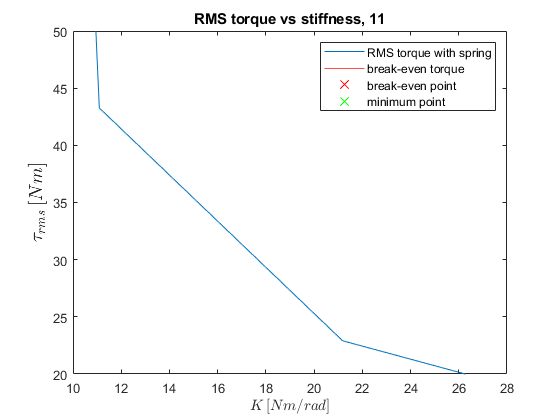

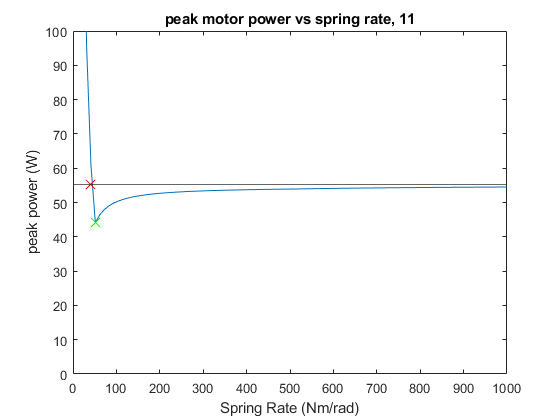

Tgait = 1.2000

overload = 1.2000

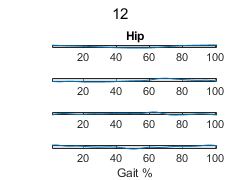

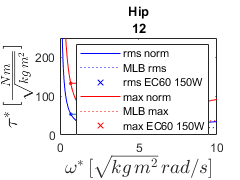

Nfeasrange =     0.1958   21.7502
    0.8908   98.9802


Nsel = 81

speed_margin = 0.1858

moment_margin_rms = 0.6351

moment_margin_max = 0.7164

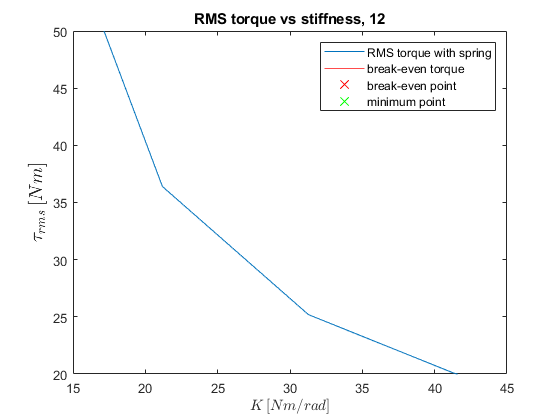

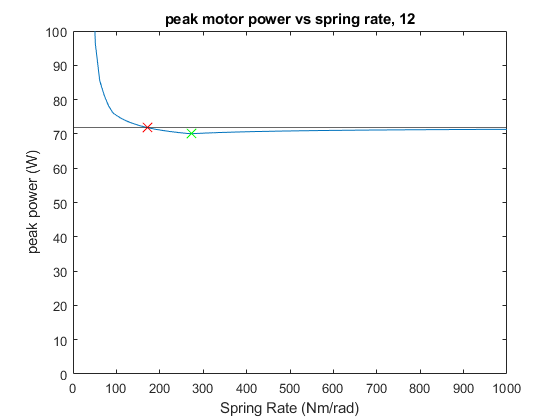

Tgait = 1.2000

overload = 1.2000

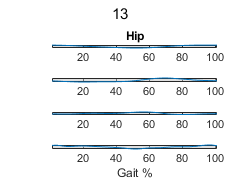

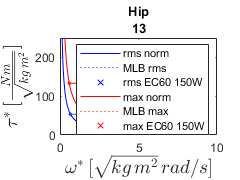

Nfeasrange =     0.2257   25.0790
    1.0945  121.6166


Nsel = 81

speed_margin = 0.3352

moment_margin_rms = 0.5984

moment_margin_max = 0.6388

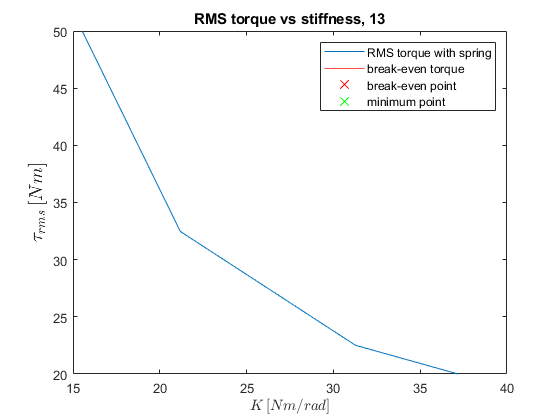

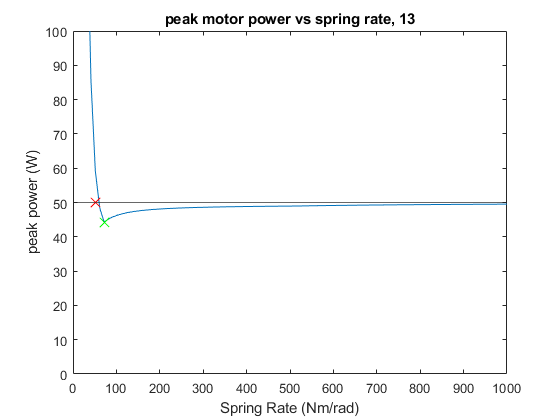

Tgait = 1.2000

overload = 1.2000

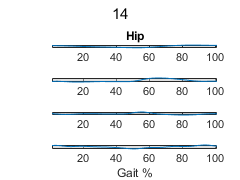

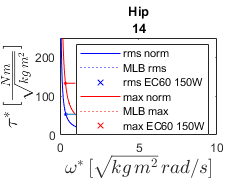

Nfeasrange =     0.1598   17.7555
    1.3582  150.9107


Nsel = 81

speed_margin = 0.4648

moment_margin_rms = 0.7081

moment_margin_max = 0.6959

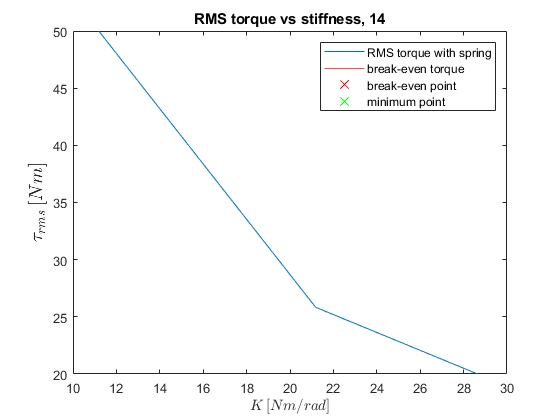

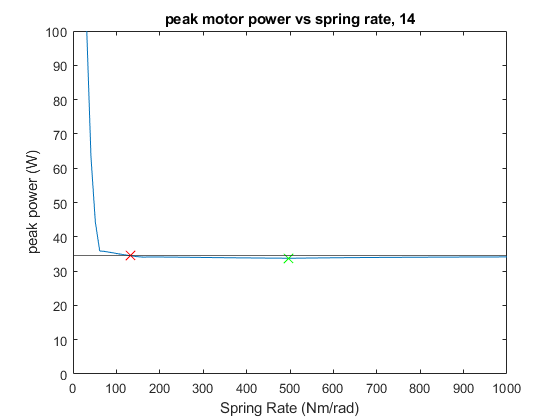

Tgait = 1.2000

overload = 1.2000

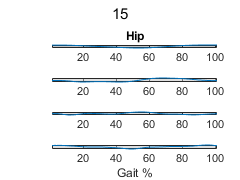

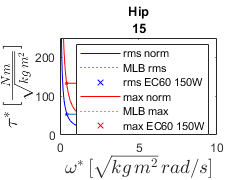

Nfeasrange =     0.1778   19.7528
    1.2923  143.5872


Nsel = 81

speed_margin = 0.4375

moment_margin_rms = 0.6629

moment_margin_max = 0.6771

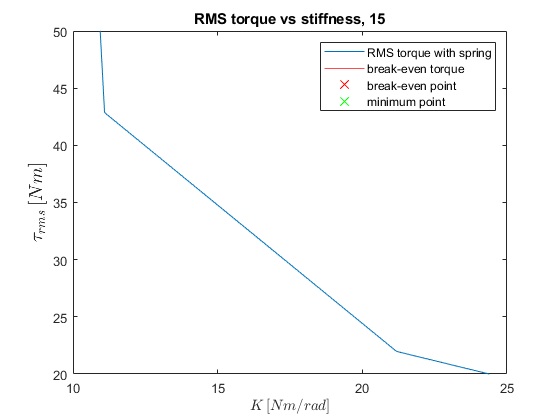

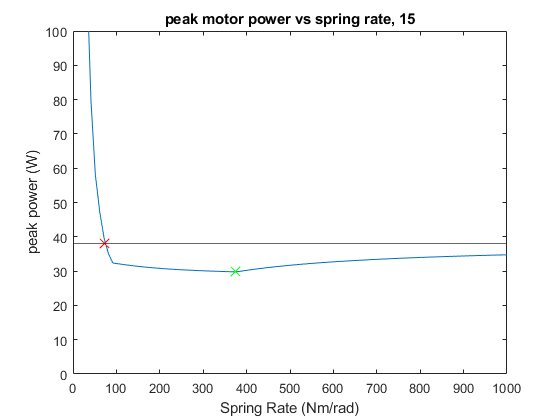

Tgait = 1.2000

overload = 1.2000

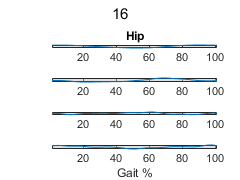

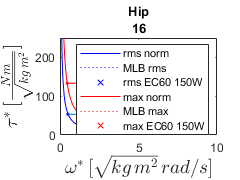

Nfeasrange =     0.1958   21.7502
    1.2324  136.9294


Nsel = 81

speed_margin = 0.4097

moment_margin_rms = 0.6489

moment_margin_max = 0.7000

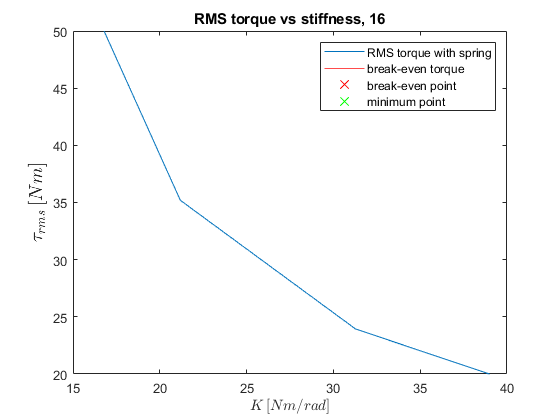

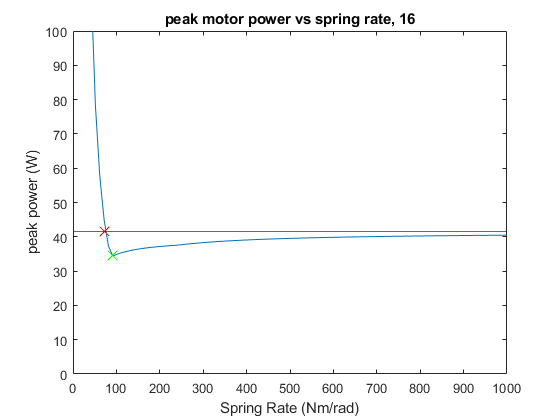

Tgait = 1.2000

overload = 1.2000

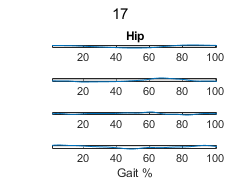

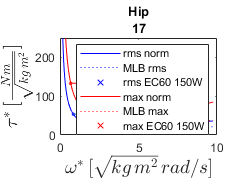

Nfeasrange =     0.2677   29.7395
    1.0047  111.6299


Nsel = 81

speed_margin = 0.2772

moment_margin_rms = 0.5582

moment_margin_max = 0.6595

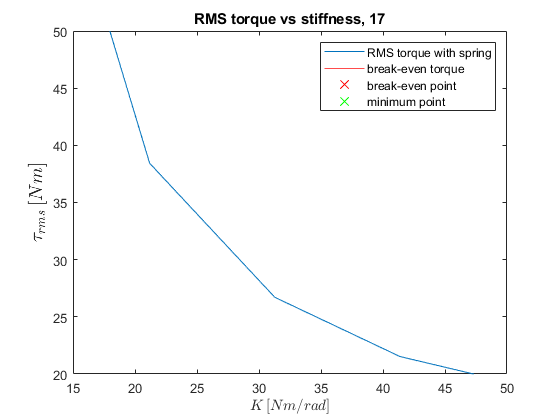

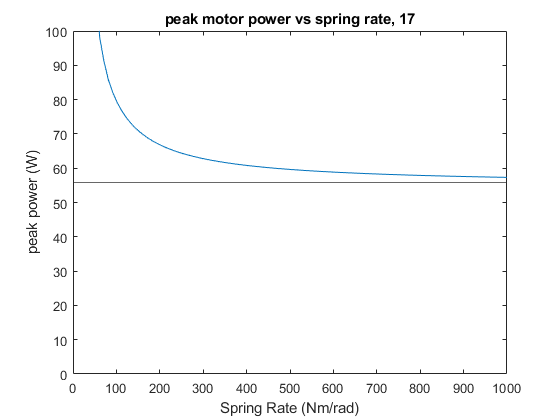

Tgait = 1.2000

overload = 1.2000

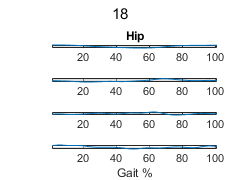

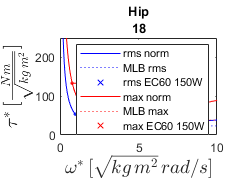

Nfeasrange =     0.2677   29.7395
    0.8788   97.6486


Nsel = 81

speed_margin = 0.1722

moment_margin_rms = 0.5305

moment_margin_max = 0.6860

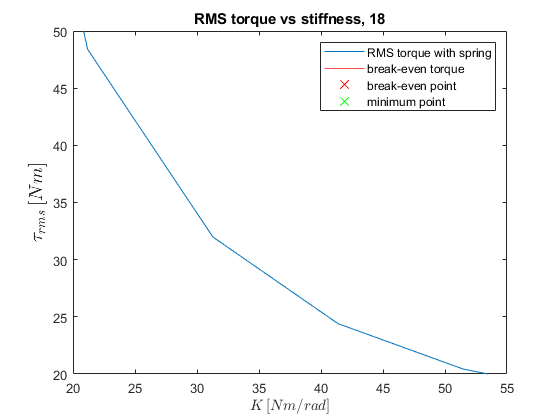

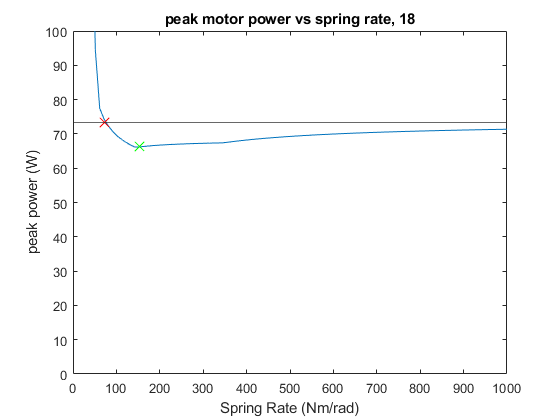

Tgait = 1.2000

overload = 1.2000

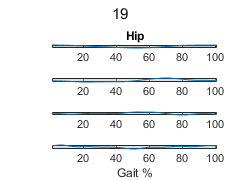

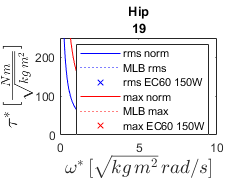

Nfeasrange =     0.4175   46.3839
    1.0346  114.9588


Nsel = 81

speed_margin = 0.2979

moment_margin_rms = 0.3607

moment_margin_max = 0.3602

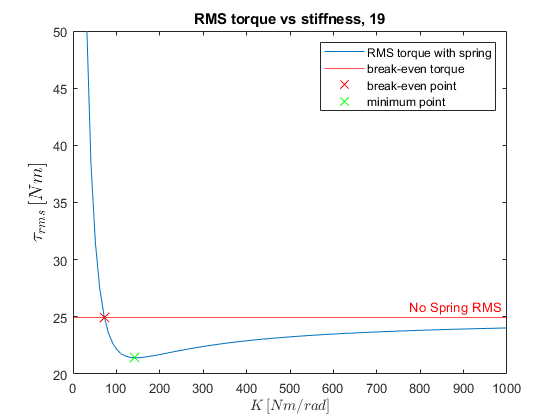

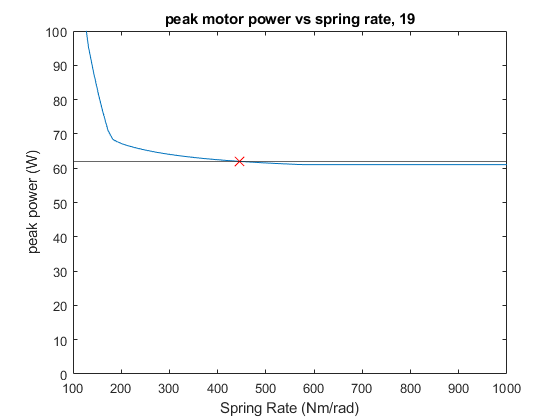

Tgait = 1.2000

overload = 1.2000

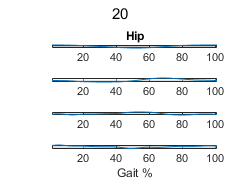

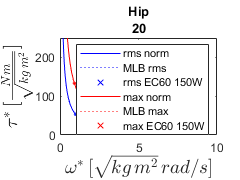

Nfeasrange =     0.3336   37.0630
    1.0886  120.9508


Nsel = 81

speed_margin = 0.3305

moment_margin_rms = 0.4582

moment_margin_max = 0.4975

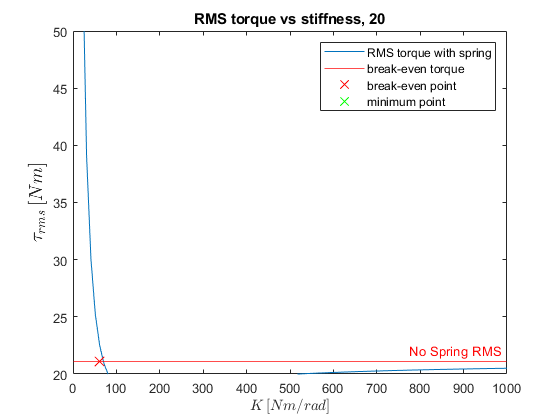

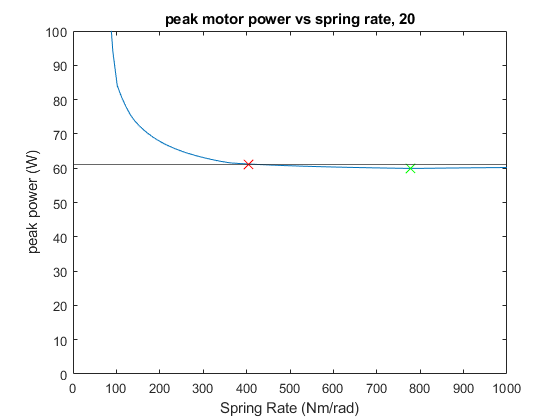

Tgait = 1.2000

overload = 1.2000

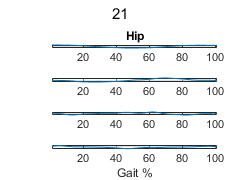

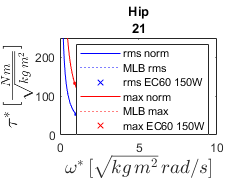

Nfeasrange =     0.3456   38.3946
    1.1065  122.9481


Nsel = 81

speed_margin = 0.3421

moment_margin_rms = 0.4449

moment_margin_max = 0.4894

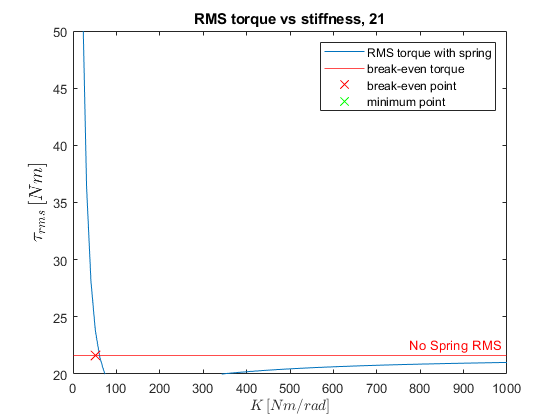

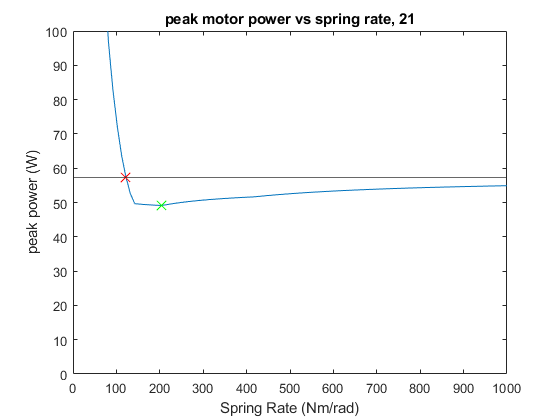

Tgait = 1.2000

overload = 1.2000

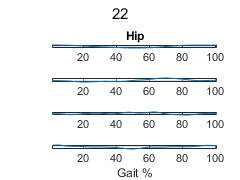

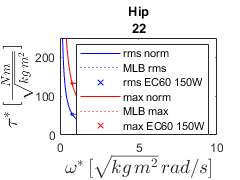

Nfeasrange =     0.2557   28.4079
    1.0586  117.6219


Nsel = 81

speed_margin = 0.3139

moment_margin_rms = 0.5696

moment_margin_max = 0.5734

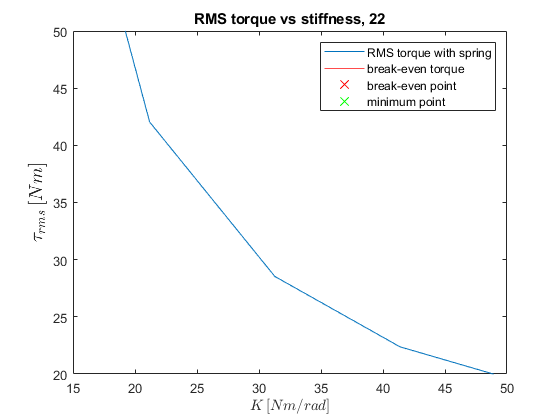

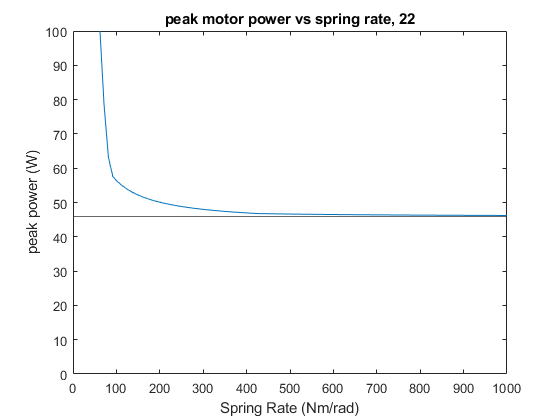

Tgait = 1.2000

overload = 1.2000

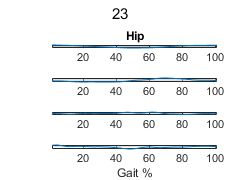

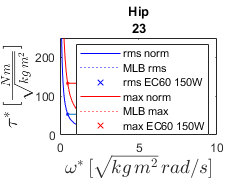

Nfeasrange =     0.2017   22.4159
    1.3163  146.2503


Nsel = 81

speed_margin = 0.4474

moment_margin_rms = 0.6536

moment_margin_max = 0.6512

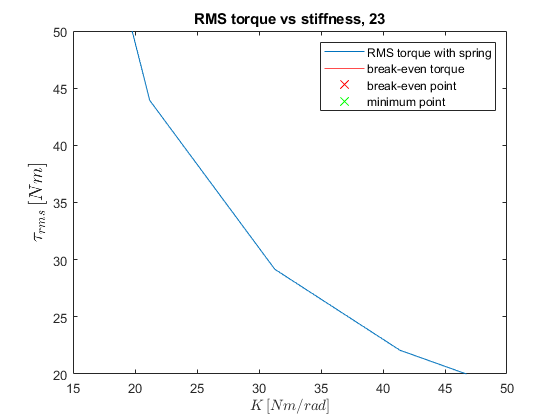

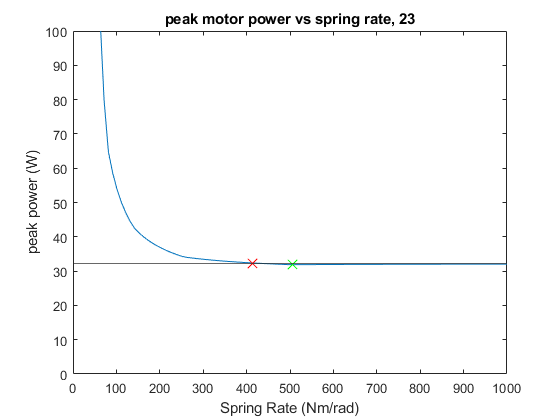

Tgait = 1.2000

overload = 1.2000

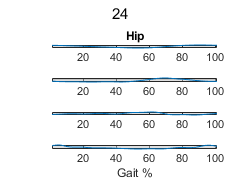

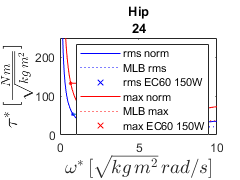

Nfeasrange =     0.2497   27.7422
    0.9747  108.3010


Nsel = 81

speed_margin = 0.2548

moment_margin_rms = 0.5675

moment_margin_max = 0.6825

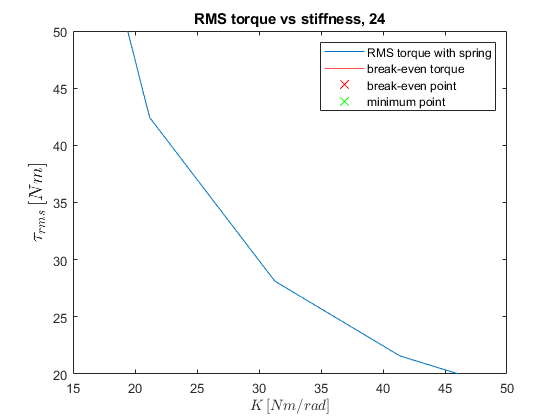

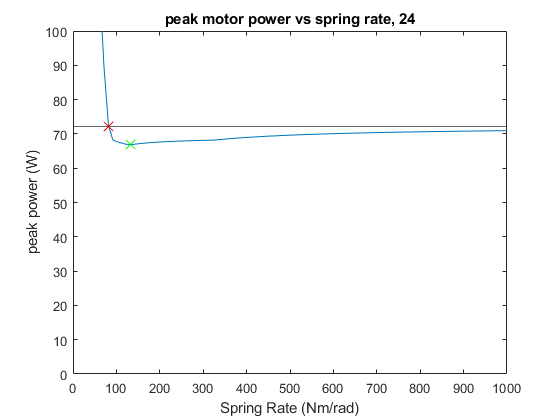

Tgait = 1.2000

overload = 1.2000

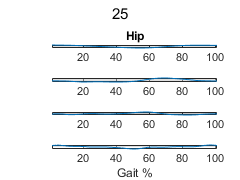

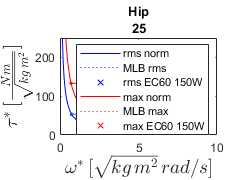

Nfeasrange =     0.2677   29.7395
    1.1665  129.6059


Nsel = 81

speed_margin = 0.3770

moment_margin_rms = 0.5587

moment_margin_max = 0.5779

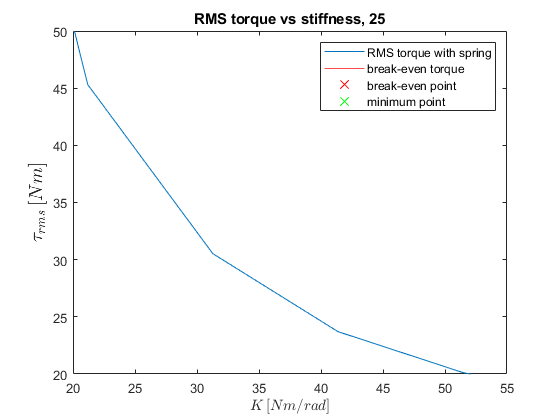

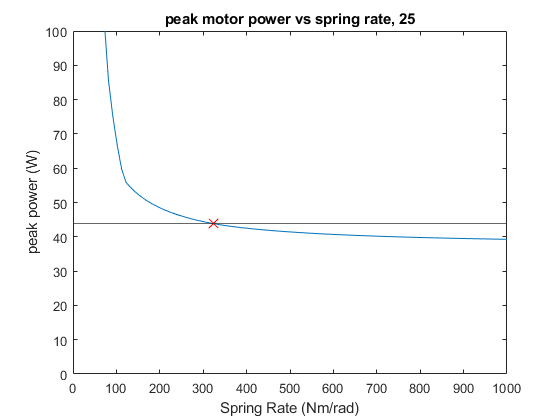

Tgait = 1.2000

overload = 1.2000

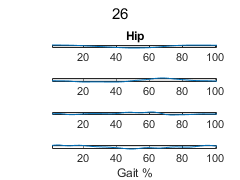

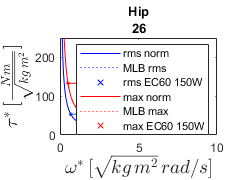

Nfeasrange =     0.2377   26.4106
    1.1065  122.9481


Nsel = 81

speed_margin = 0.3445

moment_margin_rms = 0.5928

moment_margin_max = 0.6742

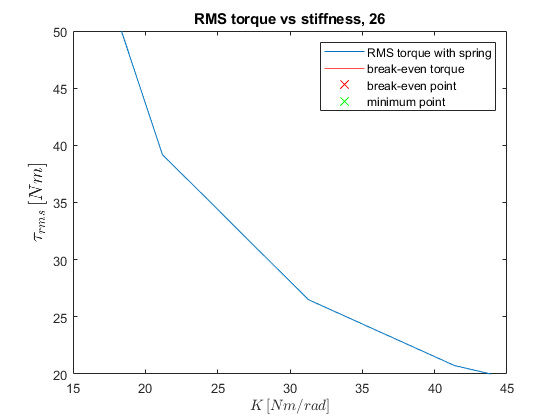

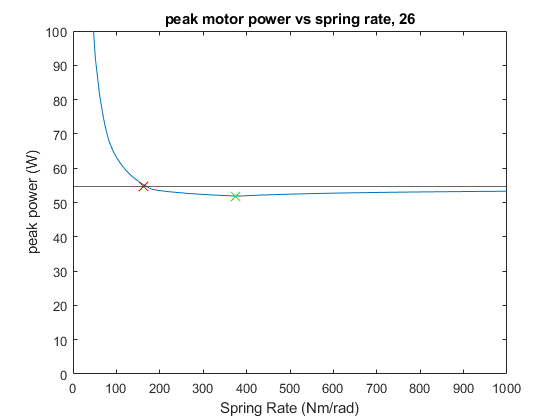

Tgait = 1.2000

overload = 1.2000

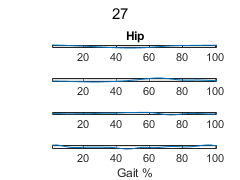

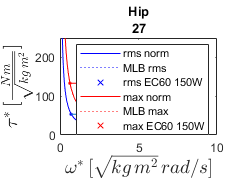

Nfeasrange =     0.2796   31.0710
    1.2623  140.2583


Nsel = 81

speed_margin = 0.4248

moment_margin_rms = 0.5499

moment_margin_max = 0.5974

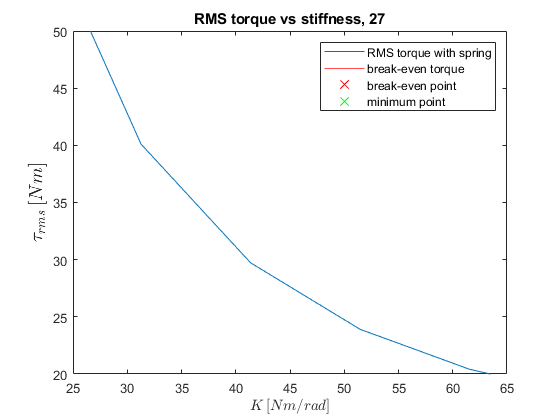

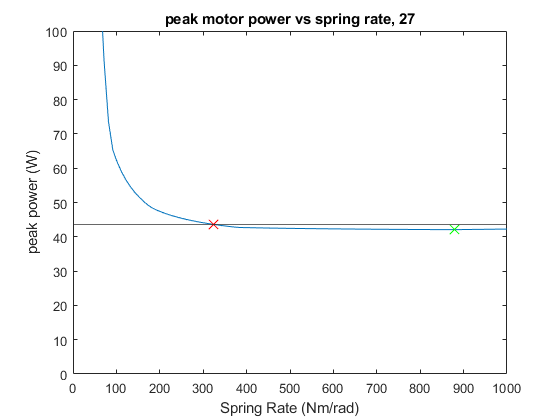

Tgait = 1.2000

overload = 1.2000

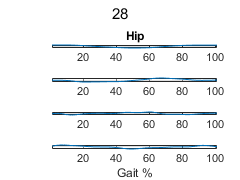

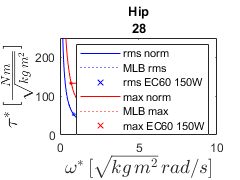

Nfeasrange =     0.3036   33.7341
    1.1305  125.6112


Nsel = 81

speed_margin = 0.3574

moment_margin_rms = 0.4991

moment_margin_max = 0.5838

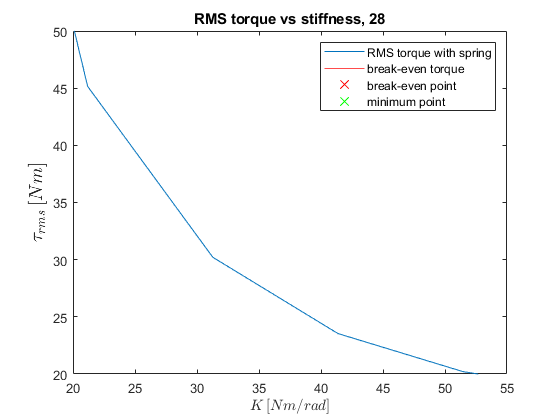

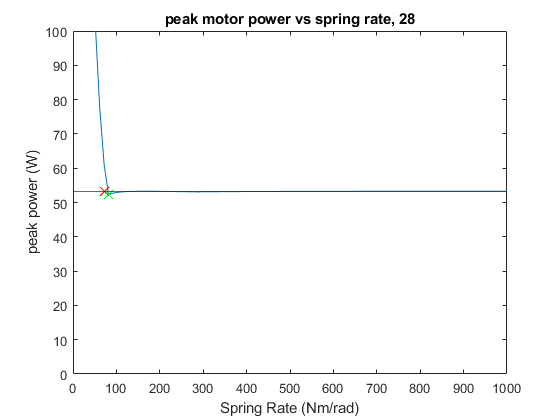

Tgait = 1.2000

overload = 1.2000

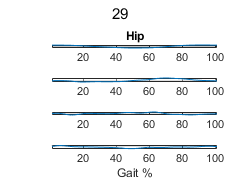

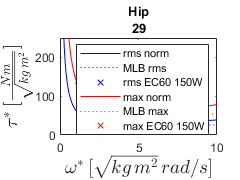

Nfeasrange =     0.3635   40.3919
    0.9807  108.9668


Nsel = 81

speed_margin = 0.2567

moment_margin_rms = 0.4253

moment_margin_max = 0.4785

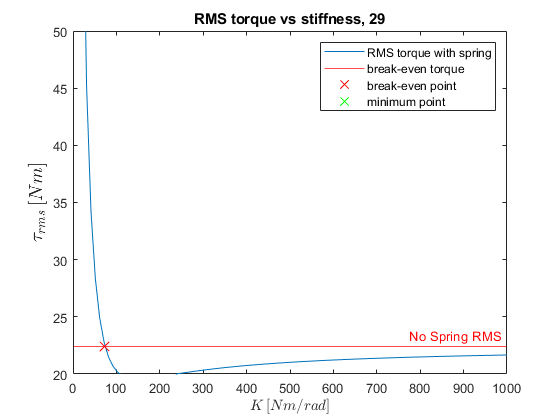

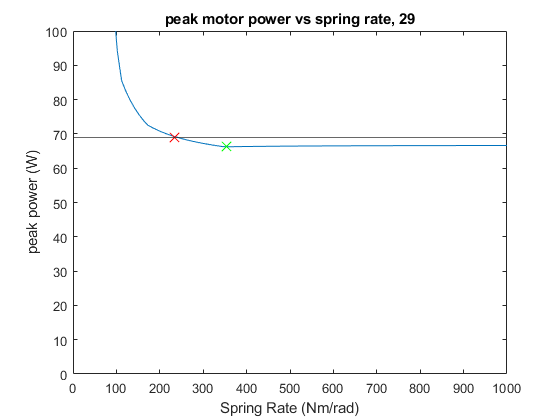

Tgait = 1.2000

overload = 1.2000

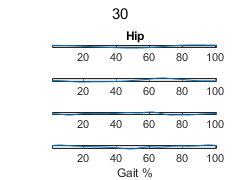

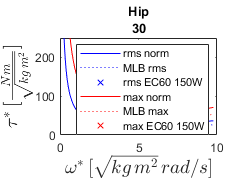

Nfeasrange =     0.3995   44.3866
    1.0047  111.6299


Nsel = 81

speed_margin = 0.2764

moment_margin_rms = 0.3882

moment_margin_max = 0.4205

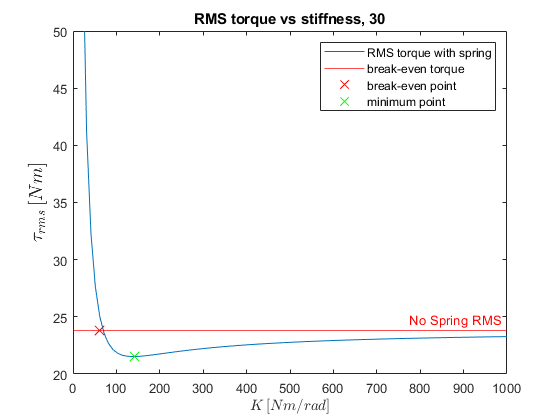

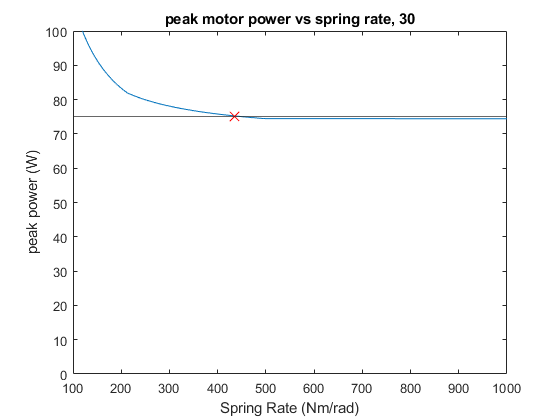

Tgait = 1.2000

overload = 1.2000

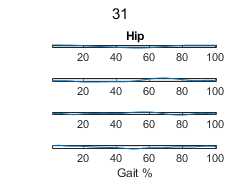

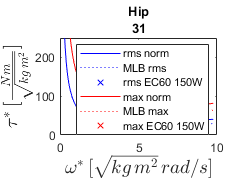

Nfeasrange =     0.4594   51.0443
    1.0047  111.6299


Nsel = 81

speed_margin = 0.2765

moment_margin_rms = 0.3062

moment_margin_max = 0.3813

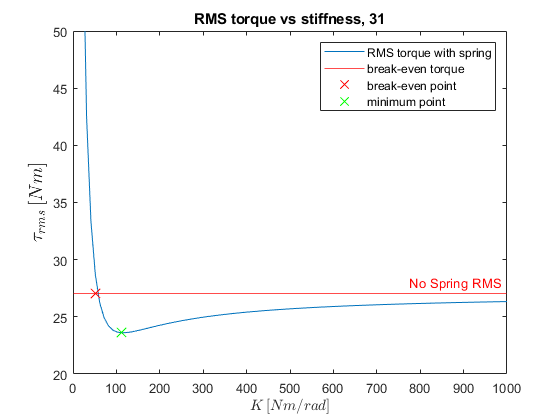

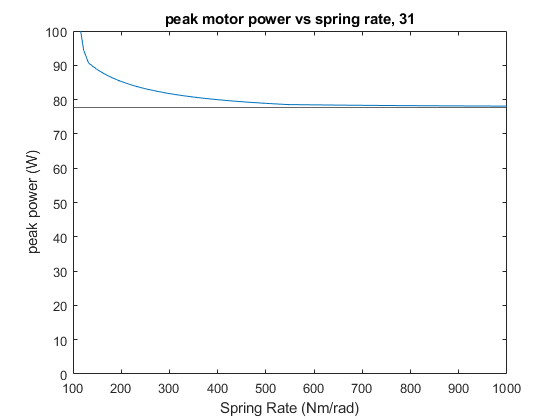

pnts = 100; % number of stifnesses to evaluate
pspring_maxabs = zeros(pnts,1);
mspring_rms = zeros(pnts,1);
KS=linspace(1,1000,pnts);

try 
    pspring_maxabs_all;
catch ME
    % init arrays
    pspring_maxabs_all = NaN(pnts, nr);
    mspring_rms_all = NaN(pnts, nr);
end


for idx=1:pnts
    
    pspring_maxabs(idx) = max(abs(((-1)*joint.m_abs*assistfactor + Bmot*Nsel^2*(joint.add+(-1)*joint.mdd*assistfactor/KS(idx))).*(joint.ad + (-1)*joint.md*assistfactor/KS(idx))));
    mspring_rms(idx) = rms(((-1)*joint.m_abs*assistfactor + Bmot*Nsel^2*(joint.add+(-1)*joint.mdd*assistfactor/KS(idx))));
    
end

pspring_maxabs_all(:,j) = pspring_maxabs;
mspring_rms_all(:,j) = mspring_rms;

mnospring = (-1)*joint.m_abs*assistfactor + Bmot*Nsel^2*(joint.add);                                %torque no spring
pnospring = mnospring.*(joint.ad);                                                                  %power no spring

mnospring_all(:,j) = mnospring';
pnospring_all(:,j) = pnospring';

[~,idpmin]=min(abs(pspring_maxabs));
[~,idmmin]=min(mspring_rms);

idpmin_all(j) = idpmin;
idmmin_all(j) = idmmin;

% spring rates that result in minimum power and moment rms
if KS(idpmin) ~= max(KS)
    KS_minPabsPeak_all(j) = KS(idpmin);
end

if KS(idmmin) ~= max(KS)
    KS_minMrms_all(j) = KS(idmmin);
end

% spring rates that result in equal power and moment rms as with no spring
% may not exist => try
try
    KS_breakevenPabsPeak_all(j)=min(KS(zci(pspring_maxabs-max(abs(pnospring)))));
catch ME
end

try
    KS_breakevenMrms_all(j)=min(KS(zci(mspring_rms-rms(mnospring))));
catch ME
end

% Plot effect of stifness on rms motor torque
figure;
plot(KS,mspring_rms)
yline(rms(mnospring),'r', 'No Spring RMS');
ylim([20,50]);
xlabel('$K\,[Nm/rad]$', "Interpreter","latex")
ylabel('$\tau_{rms}\,[Nm]$', "Interpreter","latex","FontSize",14);
title("RMS torque vs stiffness, " + pat(j));
% add break-even and minimum marker
hold on
plot(KS_breakevenMrms_all(j),rms(mnospring),'xr','MarkerSize',10)
plot(KS_minMrms_all(j),mspring_rms(idmmin),'xg','MarkerSize',10)
legend('RMS torque with spring', 'break-even torque','break-even point',  'minimum point')
hold off
set(gcf,'Visible','on')

% Plot effect of stifness on peak motor power
figure;
plot(KS,pspring_maxabs)
yline(max(abs(pnospring)));
ylim([0,100]);
xlabel('Spring Rate (Nm/rad)')
ylabel('peak power (W)')
title("peak motor power vs spring rate, " + pat(j));
% add break-even and minimum marker
hold on
try
plot(KS_breakevenPabsPeak_all(j),max(abs(pnospring)),'xr','MarkerSize',10)
plot(KS_minPabsPeak_all(j),pspring_maxabs(idpmin),'xg','MarkerSize',10)
catch ME
end
hold off
set(gcf,'Visible','on')

end % of for loop

Plot a boxplot of the feasible gearbox ratios

% figure;
% boxplot(Nfeasrange_all,"Labels",pat)
% xtickangle(90)
% hold on
% yline(Nsel,'r','Chosen Ratio','LineWidth',1)
% fig=gcf;
% set(gca,'XGrid','off','YGrid','on');
% ylim([0 210])
% title("Feasible Reduction, Hip flex-ext, Tstride =" + string(Tgait)...
%     +"s, motor " + string(actuatordata.NAME(act_id)) +...
%     ", " + string(overload)+ ", overload, "...
%     + string(assistfactor) + ", assistance")
% ylabel('Reduction ratio')
% fig.Visible = "on";

% Select a patient, 1-31
pat_spran = "31"

pat_spran = "31"

id_spran = find(strcmpi(pat,pat_spran) ,1);
joint = joint_all(id_spran);
pnospring = pnospring_all(:, id_spran)';
mnospring = mnospring_all(:, id_spran)';
pspring_maxabs = pspring_maxabs_all(:,id_spran);
mspring_rms = mspring_rms_all(:,id_spran);
idpmin = idpmin_all(id_spran);
idmmin = idmmin_all(id_spran);

% Select a spring constant
Ksel = 220;

% Altered gait profiles due to spring
joint.adsel = (joint.ad + (-1)*joint.md*assistfactor/Ksel);
joint.addsel = (joint.add+(-1)*joint.mdd*assistfactor/Ksel);
joint.msel = ((-1)*joint.m_abs*assistfactor + Bmot*Nsel^2*joint.addsel);
joint.psel = joint.msel.*joint.adsel;

% Motor power plot, with and without spring
figure;
plot(joint.psel)
hold on
plot(pnospring)
legend({'motor power with spring','motor power without spring'},"Location","best");
xlim([0 100]);
xlabel('Gait Phase (%)')
ylabel('Power (W)')
title("Motor power with spring vs no spring, Hip flex-ext, " + pat_spran + ", K=" +string(Ksel) + " Nm/rad")
mean(joint.psel)

ans = 2.1313

mean(pnospring)

ans = 3.8709

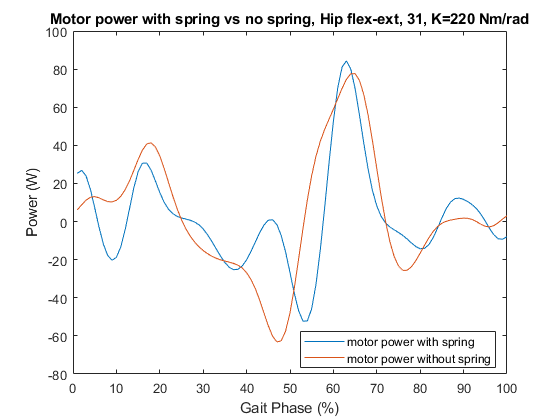

hold off
set(gcf,'Visible','on')


% Motor torque plot, with and without spring
figure;
plot(joint.msel);
hold on
plot(mnospring)
legend({'motor torque with spring','motor torque without spring'},"Location","best");
xlim([0 100]);
xlabel('Gait Phase (%)')
ylabel('Load Moment (Nm)')
title("Motor torque with spring vs no spring, Hip flex-ext, " + pat_spran + ", K=" +string(Ksel) + " Nm/rad")
hold off
rms(joint.msel)

ans = 24.4305

rms(mnospring)

ans = 27.0436

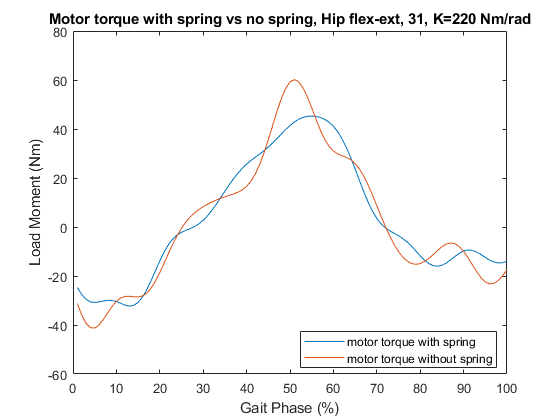

set(gcf,'Visible','on')


% Motor velocity plot, with and without spring
figure;
plot(joint.adsel)
hold on
plot(joint.ad)
legend({'motor speed with spring','motor speed without spring'},"Location","best");
rms(joint.adsel)

ans = 1.2464

rms(joint.ad)

ans = 1.5748

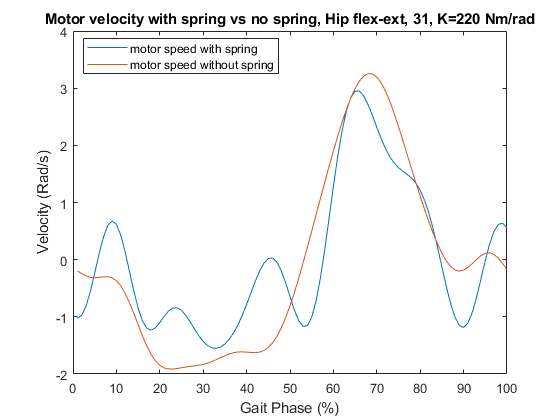

xlim([0 100]);
xlabel('Gait Phase (%)')
ylabel('Velocity (Rad/s)')
title("Motor velocity with spring vs no spring, Hip flex-ext, " + pat_spran + ", K=" +string(Ksel) + " Nm/rad")
hold off
set(gcf,'Visible','on')

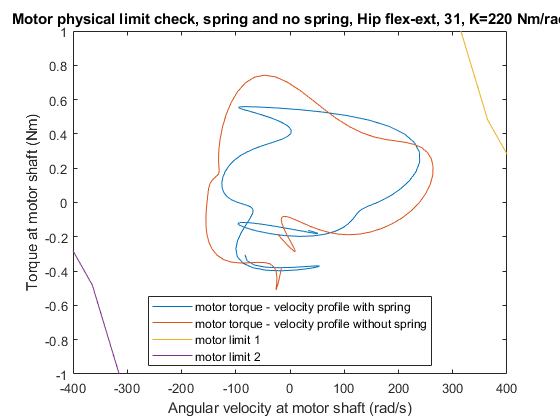


% Verify that profiles are withing motor physical limits due to back emf
figure;
plot(joint.adsel*Nsel,joint.msel/Nsel)
hold on
plot(joint.ad*Nsel,mnospring/Nsel)
vec_w= [0 wnom wnoload];
vec_T= [Tstall Tnom 0];
plot(vec_w,vec_T,-1*vec_w, -1*vec_T)
xlim([-400, 400]);
ylim([-1 1]);
legend({'motor torque - velocity profile with spring', 'motor torque - velocity profile without spring', 'motor limit 1', 'motor limit 2'}, "Location","best")
xlabel('Angular velocity at motor shaft (rad/s)')
ylabel('Torque at motor shaft (Nm)')
title("Motor physical limit check, spring and no spring, Hip flex-ext, " + pat_spran + ", K=" +string(Ksel) + " Nm/rad")
hold off
set(gcf,'Visible','on')


% Plot effect of stifness on rms motor torque
figure;
plot(KS,mspring_rms)
yline(rms(mnospring),'r', 'No Spring RMS');
ylim([20,50]);
xlabel('$K\,[Nm/rad]$', "Interpreter","latex")
ylabel('$\tau_{rms}\,[Nm]$', "Interpreter","latex","FontSize",14);
title("RMS torque vs stiffness, " + pat_spran);
% add break-even and minimum marker
hold on
plot(KS_breakevenMrms_all(id_spran),rms(mnospring),'xr','MarkerSize',10)
plot(KS_minMrms_all(id_spran),mspring_rms(idmmin),'xg','MarkerSize',10)
legend('RMS torque with spring', 'break-even torque','break-even point',  'minimum point')
hold off
set(gcf,'Visible','on')

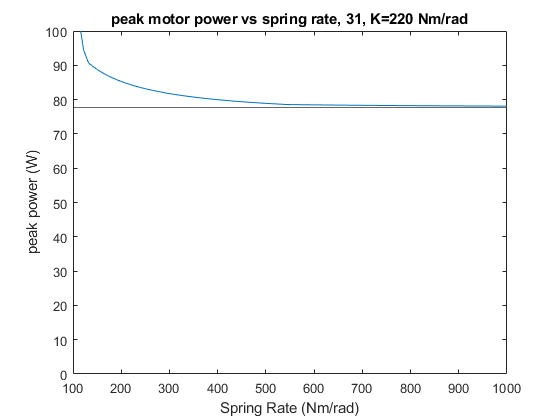


% Plot effect of stifness on peak motor power
figure;
plot(KS,pspring_maxabs)
yline(max(abs(pnospring)));
ylim([0,100]);
xlabel('Spring Rate (Nm/rad)')
ylabel('peak power (W)')
title("peak motor power vs spring rate, " + pat_spran + ", K=" +string(Ksel) + " Nm/rad");
% add break-even and minimum marker
hold on
plot(KS_breakevenPabsPeak_all(id_spran),max(abs(pnospring)),'xr','MarkerSize',10)
plot(KS_minPabsPeak_all(id_spran),pspring_maxabs(idpmin),'xg','MarkerSize',10)
hold off
set(gcf,'Visible','on')

Plot a boxplot for the statistical analysis of the possible stifness lower bound criteria

hold off

fig2=figure;
boxplot([KS_breakevenPabsPeak_all;KS_minPabsPeak_all;KS_breakevenMrms_all;KS_minMrms_all]','labels',{'K_eq,P','K_min,P','K_eq,M','K_min,M'});
% boxplot([KS_breakevenMrms_all;KS_minMrms_all]','labels',{'K_eq,M','K_min,M'});
ylabel('$K\,[Nm/rad]$', "Interpreter","latex");
ylim([0 1000]);
yline(Ksel, 'r', 'Selected Stiffness');
set(gca,'XGrid','off','YGrid','on');
title('Break-even and minimum RMS torque stiffness');
Kstats=[meanstdminmaxCV(KS_breakevenPabsPeak_all)'...
    meanstdminmaxCV(KS_minPabsPeak_all)' ...
    meanstdminmaxCV(KS_breakevenMrms_all)' ...
    meanstdminmaxCV(KS_minMrms_all)']

Kstats =   163.2618  271.1612   58.6158  127.9501
  141.0599  231.5980   13.0776   25.0956
   41.3636   51.4545   31.2727   81.7273
  445.0000  878.9091   81.7273  172.5455
    0.8640    0.8541    0.2231    0.1961


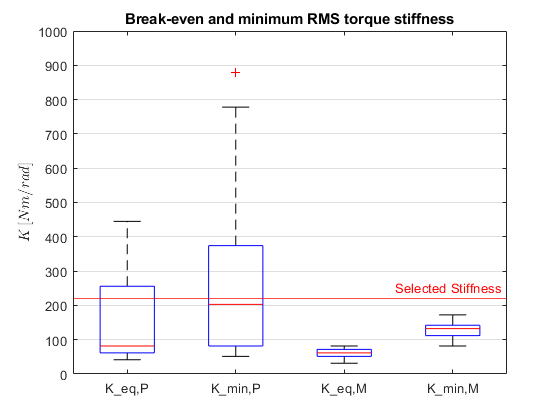

fig2.Visible = "on";

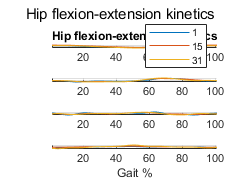

plotpat_multi_hiponly(pat, joint_all, [1 15 31]) 